## Ali Saeizadeh - 810196477

## Section 1

### 1.

cd 'F:\University\Semester IIX 2021\Communications Lab\Labs\Lab6'
clear all; clc; close all;
dcl_init;
rng(1);
pkt_size = 1e5;
b_tx = bit_gen(pkt_size, k)

b_tx =      0     0
     1     1
     0     0
     0     0
     0     1
     0     1
     0     1
     0     0
     0     0
     1     0


### 2.

if(modulation == 'fsk')
    flg_gray_encode = 0
end

flg_gray_encode = 0

if(flg_gray_encode == 1)
    b_code = gray_code(k)    
else
    b_code = non_code(k) 
end 

b_code =      0     0
     0     1
     1     0
     1     1



sym_idx = zeros(size(b_tx,1),1);
for i=1:size(b_tx,1)
    sym_idx(i,1) = find(sum(b_code == b_tx(i,:),2) == k);
end
sym_idx

sym_idx =      1
     4
     1
     1
     2
     2
     2
     1
     1
     3


### 3

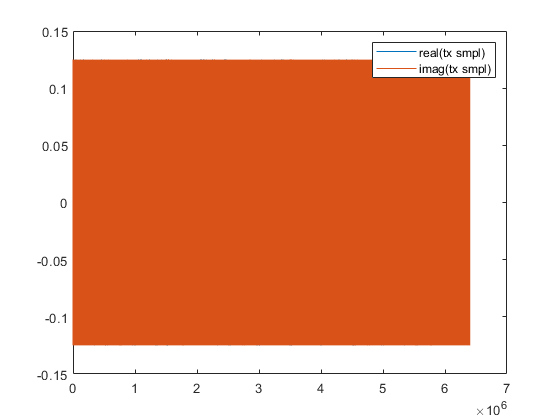

[tx_smpl, ~] = pulse_modulation(sym_idx, modulation, M, fs, smpl_per_symbl, pulse_name, pulse_gen_mode);
figure
plot([real(tx_smpl),imag(tx_smpl)])
legend('real(tx smpl)','imag(tx smpl)')

tx_smpl_delayed = [zeros(chnl_delay_in_smpl,1); tx_smpl];
rx_smpl = tx_smpl_delayed .* exp(1i*chnl_phase_offset);

Eb =  1/log2(M) 

Eb = 0.5000

EbNo = db2pow(snr_max)

EbNo = 10

var_noise = (Eb ./ EbNo)

var_noise = 0.0500

mean_noise = 0

mean_noise = 0

noise_smpl = sqrt(var_noise/2) .* (randn(size(rx_smpl)) + 1i * randn(size(rx_smpl))) + mean_noise

noise_smpl =    0.0869 - 0.2539i
   0.2025 + 0.1060i
   0.0870 - 0.0580i
   0.0918 + 0.0734i
   0.1214 + 0.0699i
   0.0129 - 0.0083i
  -0.0629 - 0.0404i
   0.0052 - 0.1901i
  -0.1422 + 0.0841i
  -0.0103 + 0.1834i


rx_smpl_noise = rx_smpl + noise_smpl

rx_smpl_noise =    0.2119 - 0.2539i
   0.3275 + 0.1060i
   0.2120 - 0.0580i
   0.2168 + 0.0734i
   0.2464 + 0.0699i
   0.1379 - 0.0083i
   0.0621 - 0.0404i
   0.1302 - 0.1901i
  -0.0172 + 0.0841i
   0.1147 + 0.1834i


modulation, M, fs, smpl_per_symbl, pulse_name , rx_mode

modulation = 'fsk'

M = 4

fs = 10000000

smpl_per_symbl = 64

pulse_name = 'rectangular'

rx_mode = 'matched_filter'

[det_sym_idx, rx_sym] = pulse_demodulation(rx_smpl_noise, modulation, M, fs, smpl_per_symbl, pulse_name , rx_mode);

det_bit = b_code(det_sym_idx,:)

det_bit =      0     0
     1     1
     0     0
     0     0
     0     1
     0     1
     0     1
     0     0
     0     0
     1     0


ser = sum(det_sym_idx ~= sym_idx)/length(sym_idx)

ser = 1.0000e-05

ber = sum(sum(det_bit ~= b_tx))/(size(det_bit, 1)*size(det_bit, 2))

ber = 5.0000e-06

serFSK = zeros(size(snr_db));
berFSK = zeros(size(snr_db));
for i = 0:1:10
    Eb =  1/log2(M);
    EbNo = db2pow(i);
    var_noise = (Eb ./ EbNo);
    mean_noise = 0;
    noise_smpl = sqrt(var_noise/2) .* (randn(size(rx_smpl)) + 1i * randn(size(rx_smpl))) + mean_noise;
    rx_smpl_noise = rx_smpl + noise_smpl;
    rx_smpl_eq = rx_smpl_noise;
    [det_sym_idx, rx_sym] = pulse_demodulation(rx_smpl_eq, modulation, M, fs, smpl_per_symbl, pulse_name , rx_mode);
    det_bit = b_code(det_sym_idx,:);
    serFSK(i + 1) = sum(det_sym_idx ~= sym_idx)/length(sym_idx);
    berFSK(i + 1) = sum(sum(det_bit ~= b_tx))/(size(det_bit, 1)*size(det_bit, 2));
end


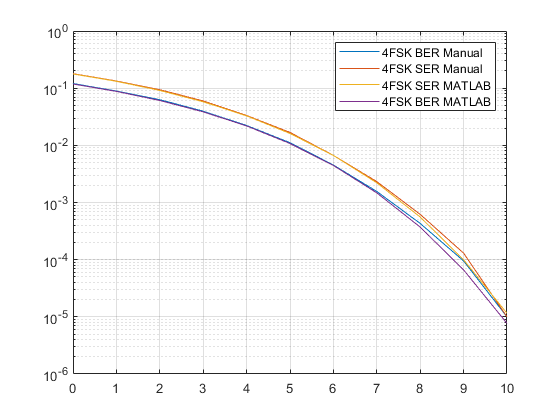

figure
[berFSK_matlab, serFSK_matlab] = berawgn(snr_db,modulation,M,'coherence');
semilogy(snr_db,berFSK)
hold on
semilogy(snr_db,serFSK)
hold on
semilogy(snr_db,serFSK_matlab)
hold on
semilogy(snr_db,berFSK_matlab)
legend('4FSK BER Manual','4FSK SER Manual', '4FSK SER MATLAB', '4FSK BER MATLAB')
grid on

figure

As we can see in plots our BER  implementation matchs MATLAB BER plot.

cd 'F:\University\Semester IIX 2021\Communications Lab\Labs\Lab6'
clear all; clc; close all;
dcl_init;
modulation = 'fsk';             
k = 1;
M = 2^k; 
rng(1);
pkt_size = 1e5;
b_tx = bit_gen(pkt_size, k);
if(modulation == 'fsk')
    flg_gray_encode = 0
end

flg_gray_encode = 0

if(flg_gray_encode == 1)
    b_code = gray_code(k)    
else
    b_code = non_code(k) 
end 

b_code =      0
     1



sym_idx = zeros(size(b_tx,1),1);
for i=1:size(b_tx,1)
    sym_idx(i,1) = find(sum(b_code == b_tx(i,:),2) == k);
end
[tx_smpl, ~] = pulse_modulation(sym_idx, modulation, M, fs, smpl_per_symbl, pulse_name, pulse_gen_mode, 1);


$$\Delta f = \frac{1}{2 
T_s}$$


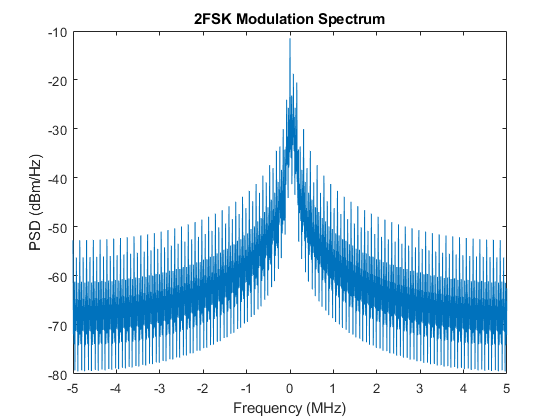

[s, freq] = spectral_dens(tx_smpl, fs, 2048);
plot(freq./1e6, s)
title('2FSK Modulation Spectrum')
xlabel('Frequency (MHz)')
ylabel('PSD (dBm/Hz)')


$$\Delta f
 = \frac{2}{T_s}$$


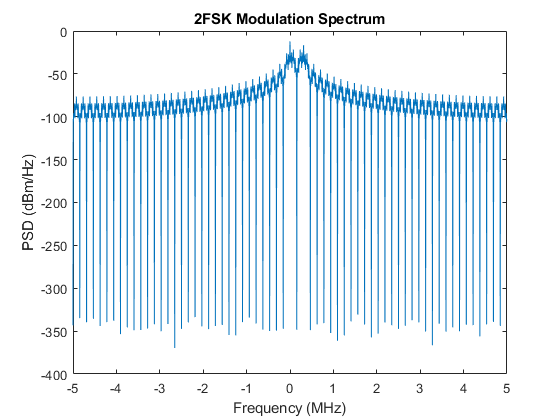

[tx_smpl, ~] = pulse_modulation(sym_idx, modulation, M, fs, smpl_per_symbl, pulse_name, pulse_gen_mode, 4);
[s, freq] = spectral_dens(tx_smpl, fs, 2048);
plot(freq./1e6, s)
title('2FSK Modulation Spectrum')
xlabel('Frequency (MHz)')
ylabel('PSD (dBm/Hz)')

As we can see in both plot by using $\Delta f_{min}
$ we use our bandwidth efficiently so by increasing $\Delta f
$ we just used more bandwidth that was NOT necessary

## Time Delay Effect

cd 'F:\University\Semester IIX 2021\Communications Lab\Labs\Lab6'
clear all; clc; close all;
dcl_init;
modulation = 'fsk';             
k = 1;
M = 2^k; 
rng(1);
pkt_size = 1e5;
b_tx = bit_gen(pkt_size, k);
if(modulation == 'fsk')
    flg_gray_encode = 0
end

flg_gray_encode = 0

if(flg_gray_encode == 1)
    b_code = gray_code(k)    
else
    b_code = non_code(k) 
end 

b_code =      0
     1



sym_idx = zeros(size(b_tx,1),1);
for i=1:size(b_tx,1)
    sym_idx(i,1) = find(sum(b_code == b_tx(i,:),2) == k);
end
[tx_smpl, ~] = pulse_modulation(sym_idx, modulation, M, fs, smpl_per_symbl, pulse_name, pulse_gen_mode);

delays_c = round([0, 0.1, 0.5, 0.8] * smpl_per_symbl)

delays_c =      0     6    32    51



serFSK = zeros(length(delays_c), length(snr_db));
berFSK = zeros(length(delays_c), length(snr_db));
for i = 1:length(delays_c)
    
    chnl_delay_in_smpl = delays_c(i)
    tx_smpl_delayed = [zeros(chnl_delay_in_smpl,1); tx_smpl];
    tx_smpl_delayed = tx_smpl_delayed(1:length(tx_smpl));
    rx_smpl = tx_smpl_delayed;
   
    for j = 0:1:10
        Eb =  1/log2(M);
        EbNo = db2pow(j);
        var_noise = (Eb ./ EbNo);
        mean_noise = 0;
        noise_smpl = sqrt(var_noise/2) .* (randn(size(rx_smpl)) + 1i * randn(size(rx_smpl))) + mean_noise;
        rx_smpl_noise = rx_smpl + noise_smpl;
        rx_smpl_eq = rx_smpl_noise;
        [det_sym_idx, ~] = pulse_demodulation(rx_smpl_eq, modulation, M, fs, smpl_per_symbl, pulse_name , rx_mode);
        det_bit = b_code(det_sym_idx,:);
        serFSK(i, j + 1) = sum(det_sym_idx ~= sym_idx)/length(sym_idx);
        berFSK(i, j + 1) = sum(sum(det_bit ~= b_tx))/(size(det_bit, 1)*size(det_bit, 2));
    end
end

chnl_delay_in_smpl = 0

chnl_delay_in_smpl = 6

chnl_delay_in_smpl = 32

chnl_delay_in_smpl = 51

### Time Delay Effect on BER 

serFSK

serFSK =     0.1601    0.1343    0.1055    0.0805    0.0576    0.0383    0.0240    0.0128    0.0062    0.0029    0.0008
    0.1915    0.1641    0.1367    0.1100    0.0862    0.0624    0.0447    0.0277    0.0168    0.0093    0.0043
    0.4177    0.4120    0.4061    0.3988    0.3931    0.3873    0.3849    0.3824    0.3834    0.3814    0.3825
    0.4959    0.4966    0.4955    0.4957    0.4971    0.4979    0.4968    0.4976    0.4989    0.4986    0.4995


berFSK

berFSK =     0.1601    0.1343    0.1055    0.0805    0.0576    0.0383    0.0240    0.0128    0.0062    0.0029    0.0008
    0.1915    0.1641    0.1367    0.1100    0.0862    0.0624    0.0447    0.0277    0.0168    0.0093    0.0043
    0.4177    0.4120    0.4061    0.3988    0.3931    0.3873    0.3849    0.3824    0.3834    0.3814    0.3825
    0.4959    0.4966    0.4955    0.4957    0.4971    0.4979    0.4968    0.4976    0.4989    0.4986    0.4995


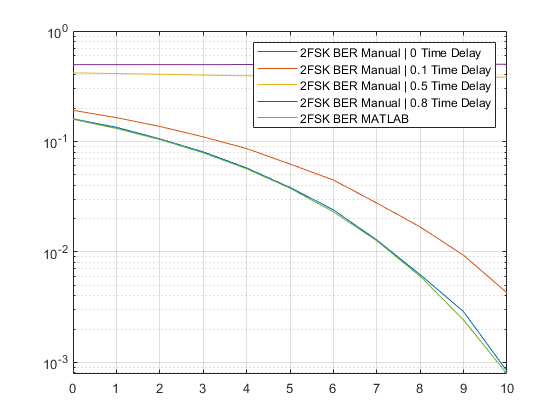

figure
[berFSK_matlab, serFSK_matlab] = berawgn(snr_db,modulation,M,'coherence');
semilogy(snr_db,berFSK(1, :))
hold on
semilogy(snr_db,berFSK(2, :))
hold on
semilogy(snr_db,berFSK(3, :))
hold on
semilogy(snr_db,berFSK(4, :))
hold on
semilogy(snr_db,berFSK_matlab)
hold on
legend('2FSK BER Manual | 0 Time Delay','2FSK BER Manual | 0.1 Time Delay', '2FSK BER Manual | 0.5 Time Delay', '2FSK BER Manual | 0.8 Time Delay', '2FSK BER MATLAB')
grid on

figure

As we can see in 0.1 time delay increase our BER about 0.03  and in 0.5 and 0.8 time delay our system totally ruined due to the time delay effect and it get worse by adding more time delay.

### Time Delay Constellation

cd 'F:\University\Semester IIX 2021\Communications Lab\Labs\Lab6'
clear all; clc; close all;
dcl_init;
modulation = 'fsk';             
k = 1;
M = 2^k; 
rng(1);
pkt_size = 1e5;
b_tx = bit_gen(pkt_size, k);
if(modulation == 'fsk')
    flg_gray_encode = 0
end

flg_gray_encode = 0

if(flg_gray_encode == 1)
    b_code = gray_code(k)    
else
    b_code = non_code(k) 
end 

b_code =      0
     1



sym_idx = zeros(size(b_tx,1),1);
for i=1:size(b_tx,1)
    sym_idx(i,1) = find(sum(b_code == b_tx(i,:),2) == k);
end
[tx_smpl, ~] = pulse_modulation(sym_idx, modulation, M, fs, smpl_per_symbl, pulse_name, pulse_gen_mode);

delays_c = round([0, 0.1, 0.5, 0.8] * smpl_per_symbl)

delays_c =      0     6    32    51


chnl_delay_in_smpl = 0

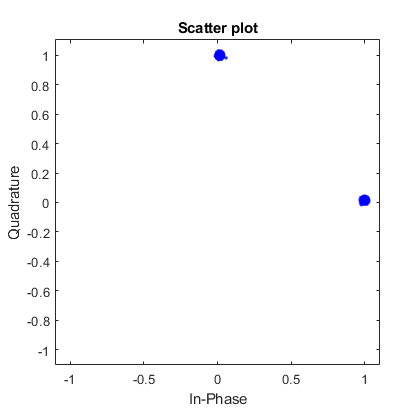

chnl_delay_in_smpl = 6

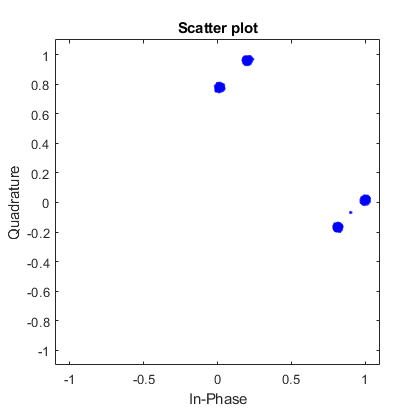

chnl_delay_in_smpl = 32

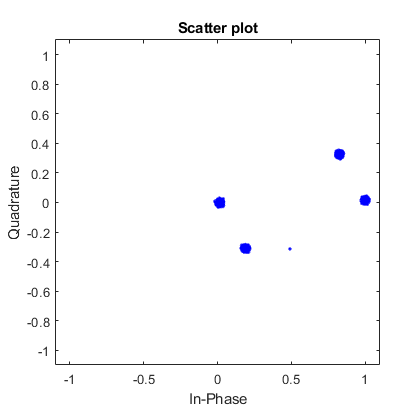

chnl_delay_in_smpl = 51

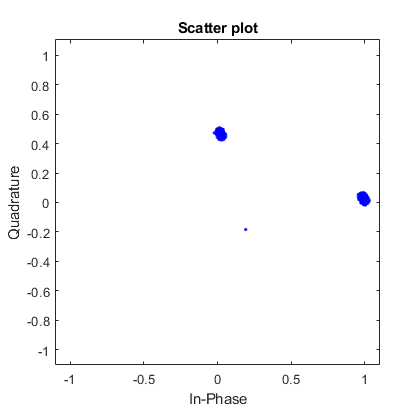

ser = zeros(length(delays_c),1);
ber = zeros(length(delays_c),1);
for i = 1:length(delays_c)
    figure
    chnl_delay_in_smpl = delays_c(i)
    tx_smpl_delayed = [zeros(chnl_delay_in_smpl,1); tx_smpl];
    tx_smpl_delayed = tx_smpl_delayed(1:length(tx_smpl));
    rx_smpl = tx_smpl_delayed;
    
    serFSK = zeros(length(delays_c), length(snr_db));
    berFSK = zeros(length(delays_c), length(snr_db));
    
    

    Eb =  1/log2(M);
    EbNo = db2pow(40);
    var_noise = (Eb ./ EbNo);
    mean_noise = 0;
    noise_smpl = sqrt(var_noise/2) .* (randn(size(rx_smpl)) + 1i * randn(size(rx_smpl))) + mean_noise;
    rx_smpl_noise = rx_smpl + noise_smpl;
    rx_smpl_eq = rx_smpl_noise;
    [det_sym_idx, rx_sym] = pulse_demodulation(rx_smpl_eq, modulation, M, fs, smpl_per_symbl, pulse_name , rx_mode);
    det_bit = b_code(det_sym_idx,:);
    scatterplot(rx_sym)

end

By adding time delay, correlators don't work as correct as before so our output constellation is wrong due to time delay effect.

## Time Delay Compensation

cd 'F:\University\Semester IIX 2021\Communications Lab\Labs\Lab6'
clear all; clc; close all;
dcl_init;
modulation = 'fsk';             
k = 1;
M = 2^k; 
rng(1);
pkt_size = 1e5;
b_tx = bit_gen(pkt_size, k);

hdr_bit = repmat(reshape(de2bi(hex2dec(['1C6387FF5DA4FA325C895958DC5']'))', [], 1),1,k)

hdr_bit =      1
     0
     0
     0
     0
     0
     1
     1
     0
     1


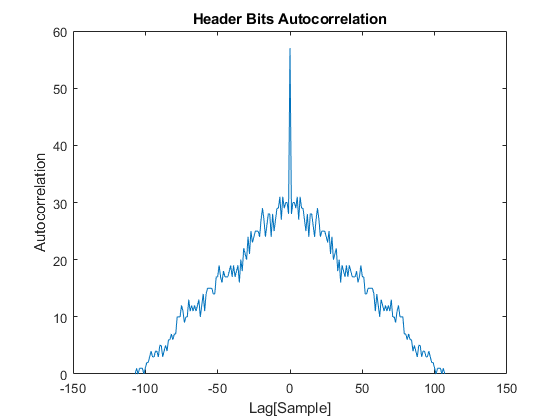

[corr_out_rx, lag] = xcorr(hdr_bit);
plot(lag, corr_out_rx);
xlabel('Lag[Sample]')
ylabel('Autocorrelation')
title('Header Bits Autocorrelation')

[corr_out_rx_max, idx_max] = max(corr_out_rx)

corr_out_rx_max = 57

idx_max = 108

b_tx = [hdr_bit; b_tx];

if(modulation == 'fsk')
    flg_gray_encode = 0
end

flg_gray_encode = 0

if(flg_gray_encode == 1)
    b_code = gray_code(k)    
else
    b_code = non_code(k) 
end 

b_code =      0
     1



sym_idx = zeros(size(b_tx,1),1);
for i=1:size(b_tx,1)
    sym_idx(i,1) = find(sum(b_code == b_tx(i,:),2) == k);
end
[tx_smpl, ~] = pulse_modulation(sym_idx, modulation, M, fs, smpl_per_symbl, pulse_name, pulse_gen_mode);


hdr_smpl = tx_smpl(1:length(hdr_bit) * smpl_per_symbl)

hdr_smpl =    0.1250 + 0.0000i
   0.1248 + 0.0061i
   0.1244 + 0.0123i
   0.1236 + 0.0183i
   0.1226 + 0.0244i
   0.1213 + 0.0304i
   0.1196 + 0.0363i
   0.1177 + 0.0421i
   0.1155 + 0.0478i
   0.1130 + 0.0534i


delays_c = round([0, 0.1, 0.5, 0.8] * smpl_per_symbl)

delays_c =      0     6    32    51




for i = 1:length(delays_c)
    chnl_delay_in_smpl = delays_c(i)
    tx_smpl_delayed = [zeros(chnl_delay_in_smpl,1); tx_smpl];
    rx_smpl = tx_smpl_delayed;
   
    for j = 1:1:10
        Eb =  1/log2(M);
        EbNo = db2pow(j);
        var_noise = (Eb ./ EbNo);
        mean_noise = 0;
        noise_smpl = sqrt(var_noise/2) .* (randn(size(rx_smpl)) + 1j * randn(size(rx_smpl))) + mean_noise;
        rx_smpl_noise = rx_smpl + noise_smpl;
        rx_smpl_eq = rx_smpl_noise;
        
        [r,lag] = xcorr(rx_smpl_eq, hdr_smpl);
        [~, idx_max] = max(r);
        estimated_time_delay = lag(idx_max);
        if(estimated_time_delay ~= chnl_delay_in_smpl)
            disp('Error')
            disp(chnl_delay_in_smpl)
            disp(estimated_time_delay)
            disp(j)
            rx_smpl_comp = rx_smpl_eq(chnl_delay_in_smpl + 1:end);
        else
            rx_smpl_comp = rx_smpl_eq(estimated_time_delay + 1:end);
        end
        
        
        [det_sym_idx, ~] = pulse_demodulation(rx_smpl_comp, modulation, M, fs, smpl_per_symbl, pulse_name , rx_mode);
        det_bit = b_code(det_sym_idx,:);
        
        serFSK(i, j + 1) = sum(det_sym_idx ~= sym_idx)/length(sym_idx);
        berFSK(i, j + 1) = sum(sum(det_bit ~= b_tx))/(size(det_bit, 1)*size(det_bit, 2));
    end
end

chnl_delay_in_smpl = 0

chnl_delay_in_smpl = 6

chnl_delay_in_smpl = 32

Error


    32



    30



     2



chnl_delay_in_smpl = 51

Error


    51



    50



     1



When we cant estimate time delay because of low SNR we just simply igonre it to not change our functions that much(size of vectors)

serFSK

serFSK =          0    0.1325    0.1057    0.0792    0.0586    0.0396    0.0244    0.0132    0.0063    0.0028    0.0009
         0    0.1325    0.1057    0.0815    0.0592    0.0394    0.0236    0.0133    0.0062    0.0027    0.0010
         0    0.1334    0.1053    0.0813    0.0574    0.0384    0.0233    0.0132    0.0064    0.0028    0.0011
         0    0.1320    0.1055    0.0807    0.0583    0.0390    0.0246    0.0127    0.0061    0.0026    0.0008


berFSK

berFSK =          0    0.1325    0.1057    0.0792    0.0586    0.0396    0.0244    0.0132    0.0063    0.0028    0.0009
         0    0.1325    0.1057    0.0815    0.0592    0.0394    0.0236    0.0133    0.0062    0.0027    0.0010
         0    0.1334    0.1053    0.0813    0.0574    0.0384    0.0233    0.0132    0.0064    0.0028    0.0011
         0    0.1320    0.1055    0.0807    0.0583    0.0390    0.0246    0.0127    0.0061    0.0026    0.0008


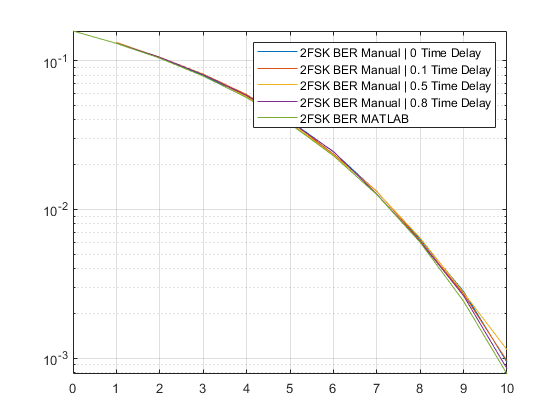

figure
[berFSK_matlab, serFSK_matlab] = berawgn(snr_db,modulation,M,'coherence');
semilogy(snr_db,berFSK(1, :))
hold on
semilogy(snr_db,berFSK(2, :))
hold on
semilogy(snr_db,berFSK(3, :))
hold on
semilogy(snr_db,berFSK(4, :))
hold on
semilogy(snr_db,berFSK_matlab)
hold on
legend('2FSK BER Manual | 0 Time Delay','2FSK BER Manual | 0.1 Time Delay', '2FSK BER Manual | 0.5 Time Delay', '2FSK BER Manual | 0.8 Time Delay', '2FSK BER MATLAB')
grid on

figure

By adding header in the beginenning of the TX bit, now we're able to estimate time delay by using cross correlation of the header.

In all  cases, our estimation of time delay is accurate and bit and symbol error is decreased to zero time delay value.

cd 'F:\University\Semester IIX 2021\Communications Lab\Labs\Lab6'
clear all; clc; close all;
dcl_init;
modulation = 'fsk';             
k = 1;
M = 2^k; 
rng(1);
pkt_size = 1e5;
b_tx = bit_gen(pkt_size, k);

hdr_bit = repmat(reshape(de2bi(hex2dec(['1C6387FF5DA4FA325C895958DC5']'))', [], 1),1,k)

hdr_bit =      1
     0
     0
     0
     0
     0
     1
     1
     0
     1


[corr_out_rx, lag] = xcorr(hdr_bit);
plot(lag, corr_out_rx);
xlabel('Lag[Sample]')
ylabel('Autocorrelation')
title('Header Bits Autocorrelation')

[corr_out_rx_max, idx_max] = max(corr_out_rx)

corr_out_rx_max = 57

idx_max = 108

b_tx = [hdr_bit; b_tx];

if(modulation == 'fsk')
    flg_gray_encode = 0
end

flg_gray_encode = 0

if(flg_gray_encode == 1)
    b_code = gray_code(k)    
else
    b_code = non_code(k) 
end 

b_code =      0
     1



sym_idx = zeros(size(b_tx,1),1);
for i=1:size(b_tx,1)
    sym_idx(i,1) = find(sum(b_code == b_tx(i,:),2) == k);
end
[tx_smpl, ~] = pulse_modulation(sym_idx, modulation, M, fs, smpl_per_symbl, pulse_name, pulse_gen_mode);


hdr_smpl = tx_smpl(1:length(hdr_bit) * smpl_per_symbl)

hdr_smpl =    0.1250 + 0.0000i
   0.1248 + 0.0061i
   0.1244 + 0.0123i
   0.1236 + 0.0183i
   0.1226 + 0.0244i
   0.1213 + 0.0304i
   0.1196 + 0.0363i
   0.1177 + 0.0421i
   0.1155 + 0.0478i
   0.1130 + 0.0534i


delays_c = round([0.5] * smpl_per_symbl)

delays_c = 32

chnl_delay_in_smpl = 32

corr_out_rx_max = 1.0608e+02 - 9.9826e-01i

idx_max = 6406976

estimated_time_delay = 32

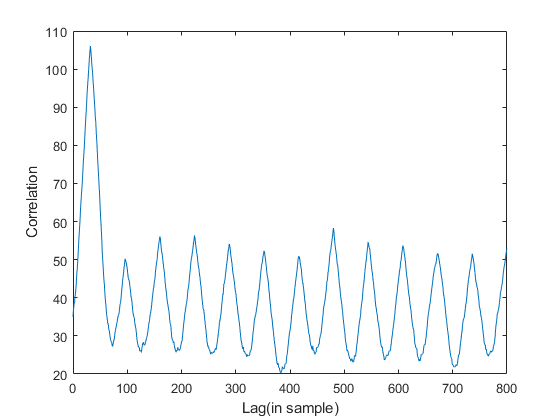

ser = zeros(length(delays_c),1);
ber = zeros(length(delays_c),1);
for i = 1:length(delays_c)
    figure
    chnl_delay_in_smpl = delays_c(i)
    tx_smpl_delayed = [zeros(chnl_delay_in_smpl,1); tx_smpl];
    rx_smpl = tx_smpl_delayed .* exp(1i*chnl_phase_offset);
    Eb =  1/log2(M) ;
    EbNo = db2pow(snr_max);
    var_noise = (Eb ./ EbNo);
    mean_noise = 0;
    noise_smpl = sqrt(var_noise/2) .* (randn(size(rx_smpl)) + 1i * randn(size(rx_smpl))) + mean_noise;
    rx_smpl_noise = rx_smpl + noise_smpl;
    
    rx_smpl_eq = rx_smpl_noise;
    [r,lag] = xcorr(rx_smpl_eq, hdr_smpl);
    [corr_out_rx_max, idx_max] = max(r)
    estimated_time_delay = lag(idx_max)
    rx_smpl_eq = rx_smpl_eq(estimated_time_delay + 1:end);
    plot(lag,real(r))
    xlabel('Lag(in sample)')
    ylabel('Correlation')
    xlim([0 800])
    
    [det_sym_idx, rx_sym] = pulse_demodulation(rx_smpl_eq, modulation, M, fs, smpl_per_symbl, pulse_name , rx_mode);
    det_bit = b_code(det_sym_idx,:);
    ser(i) = sum(det_sym_idx ~= sym_idx)/length(sym_idx);
    ber(i) = sum(sum(det_bit ~= b_tx))/(size(det_bit, 1)*size(det_bit, 2));
end

ber

ber = 9.2900e-04

ser

ser = 9.2900e-04

## Phase Offset Effect

cd 'F:\University\Semester IIX 2021\Communications Lab\Labs\Lab6'
clear all; clc; close all;
dcl_init;
modulation = 'fsk';             
k = 1;
M = 2^k; 
rng(1);
pkt_size = 1e5;
b_tx = bit_gen(pkt_size, k);
if(modulation == 'fsk')
    flg_gray_encode = 0;
end
if(flg_gray_encode == 1)
    b_code = gray_code(k) ;   
else
    b_code = non_code(k) ;
end 

sym_idx = zeros(size(b_tx,1),1);
for i=1:size(b_tx,1)
    sym_idx(i,1) = find(sum(b_code == b_tx(i,:),2) == k);
end
[tx_smpl, ~] = pulse_modulation(sym_idx, modulation, M, fs, smpl_per_symbl, pulse_name, pulse_gen_mode);

serFSK = zeros(size(snr_db));
berFSK = zeros(size(snr_db));
for i = 0:1:10
    chnl_phase_offset = pi/6;
    rx_smpl = tx_smpl .* exp(1i*chnl_phase_offset);
    Eb =  1/log2(M);
    EbNo = db2pow(i);
    var_noise = (Eb ./ EbNo);
    mean_noise = 0;
    noise_smpl = sqrt(var_noise/2) .* (randn(size(rx_smpl)) + 1i * randn(size(rx_smpl))) + mean_noise;
    rx_smpl_noise = rx_smpl + noise_smpl;
    rx_smpl_eq = rx_smpl_noise;
    [det_sym_idx, rx_sym] = pulse_demodulation(rx_smpl_eq, modulation, M, fs, smpl_per_symbl, pulse_name , rx_mode);
    det_bit = b_code(det_sym_idx,:);
    serFSK(i + 1) = sum(det_sym_idx ~= sym_idx)/length(sym_idx);
    berFSK(i + 1) = sum(sum(det_bit ~= b_tx))/(size(det_bit, 1)*size(det_bit, 2));
end

serFSK

serFSK =     0.2061    0.1841    0.1594    0.1362    0.1143    0.0935    0.0753    0.0585    0.0450    0.0323    0.0215


berFSK

berFSK =     0.2061    0.1841    0.1594    0.1362    0.1143    0.0935    0.0753    0.0585    0.0450    0.0323    0.0215


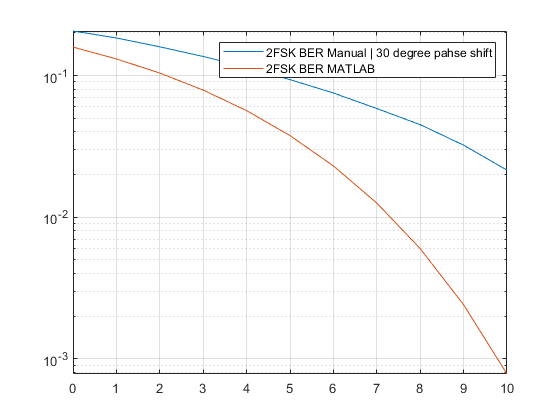

figure
[berFSK_matlab, serFSK_matlab] = berawgn(snr_db,modulation,M,'coherence');
semilogy(snr_db,berFSK)
hold on
semilogy(snr_db,berFSK_matlab)
hold on
legend('2FSK BER Manual | 30 degree pahse shift','2FSK BER MATLAB')
grid on

figure

As we can see by adding phase shift to the signal we just lost our accuracy due to the shifting all rx points in constellation by 30 degree.

cd 'F:\University\Semester IIX 2021\Communications Lab\Labs\Lab6'
clear all; clc; close all;
dcl_init;
modulation = 'fsk';             
k = 1;
M = 2^k; 
rng(1);
pkt_size = 1e5;
b_tx = bit_gen(pkt_size, k);
if(modulation == 'fsk')
    flg_gray_encode = 0;
end
if(flg_gray_encode == 1)
    b_code = gray_code(k) ;   
else
    b_code = non_code(k) ;
end 

sym_idx = zeros(size(b_tx,1),1);
for i=1:size(b_tx,1)
    sym_idx(i,1) = find(sum(b_code == b_tx(i,:),2) == k);
end
[tx_smpl, ~] = pulse_modulation(sym_idx, modulation, M, fs, smpl_per_symbl, pulse_name, pulse_gen_mode);


chnl_phase_offset = pi/6;
rx_smpl = tx_smpl .* exp(1i*chnl_phase_offset);
Eb =  1/log2(M);
EbNo = db2pow(40);
var_noise = (Eb ./ EbNo);
mean_noise = 0;
noise_smpl = sqrt(var_noise/2) .* (randn(size(rx_smpl)) + 1i * randn(size(rx_smpl))) + mean_noise;
rx_smpl_noise = rx_smpl + noise_smpl;
rx_smpl_eq = rx_smpl_noise;
[det_sym_idx, rx_sym] = pulse_demodulation(rx_smpl_eq, modulation, M, fs, smpl_per_symbl, pulse_name , rx_mode);
det_bit = b_code(det_sym_idx,:);
serFSK = sum(det_sym_idx ~= sym_idx)/length(sym_idx)

serFSK = 0

berFSK = sum(sum(det_bit ~= b_tx))/(size(det_bit, 1)*size(det_bit, 2))

berFSK = 0

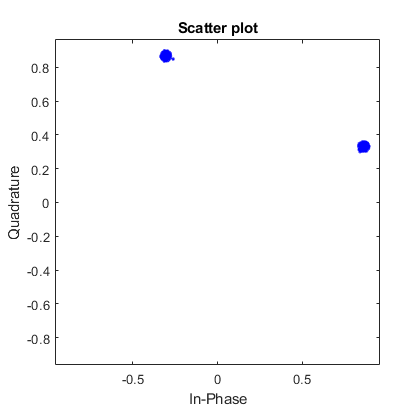

scatterplot(rx_sym)

We can see that the constellation is rotated by value of phase offset. (all points is multiplied by $e^{i \phi}$)

##  Phase Offser Compensation

cd 'F:\University\Semester IIX 2021\Communications Lab\Labs\Lab6'
clear all; clc; close all;
dcl_init;
modulation = 'fsk';             
k = 1;
M = 2^k; 
rng(1);
pkt_size = 1e5;
b_tx = bit_gen(pkt_size, k);

hdr_bit = repmat(reshape(de2bi(hex2dec(['1C6387FF5DA4FA325C895958DC5']'))', [], 1),1,k)

hdr_bit =      1
     0
     0
     0
     0
     0
     1
     1
     0
     1


[corr_out_rx, lag] = xcorr(hdr_bit);
plot(lag, corr_out_rx);
xlabel('Lag[Sample]')
ylabel('Autocorrelation')
title('Header Bits Autocorrelation')

[corr_out_rx_max, idx_max] = max(corr_out_rx)

corr_out_rx_max = 57

idx_max = 108

b_tx = [hdr_bit; b_tx];

if(modulation == 'fsk')
    flg_gray_encode = 0
end

flg_gray_encode = 0

if(flg_gray_encode == 1)
    b_code = gray_code(k)    
else
    b_code = non_code(k) 
end 

b_code =      0
     1



sym_idx = zeros(size(b_tx,1),1);
for i=1:size(b_tx,1)
    sym_idx(i,1) = find(sum(b_code == b_tx(i,:),2) == k);
end
[tx_smpl, ~] = pulse_modulation(sym_idx, modulation, M, fs, smpl_per_symbl, pulse_name, pulse_gen_mode);

hdr_smpl = tx_smpl(1:length(hdr_bit) * smpl_per_symbl)

hdr_smpl =    0.1250 + 0.0000i
   0.1248 + 0.0061i
   0.1244 + 0.0123i
   0.1236 + 0.0183i
   0.1226 + 0.0244i
   0.1213 + 0.0304i
   0.1196 + 0.0363i
   0.1177 + 0.0421i
   0.1155 + 0.0478i
   0.1130 + 0.0534i



EbNo = db2pow(snr_max)

EbNo = 10

phase_offset = [0, pi/6]

phase_offset =          0    0.5236


ser = zeros(length(phase_offset),1);
ber = zeros(length(phase_offset),1);
for i = 1:length(phase_offset)
    chnl_delay_in_smpl = 4;
    chnl_phase_offset = phase_offset(i);
    tx_smpl_delayed = tx_smpl;
    rx_smpl = tx_smpl_delayed .* exp(1i*chnl_phase_offset);
    
    Eb =  1/log2(M) ;
    EbNo = db2pow(snr_max);
    var_noise = (Eb ./ EbNo);
    mean_noise = 0;
    noise_smpl = sqrt(var_noise/2) .* (randn(size(rx_smpl)) + 1i * randn(size(rx_smpl))) + mean_noise;
    rx_smpl_noise = rx_smpl + noise_smpl;
    rx_smpl_eq = rx_smpl_noise;
    
    [r,lag] = xcorr(rx_smpl_eq, hdr_smpl);
    [corr_out_rx_max, idx_max] = max(r)
    estimated_time_delay = lag(idx_max)
    rx_smpl_eq = rx_smpl_eq(estimated_time_delay + 1:end);
    estimated_phase_offset = angle(corr_out_rx_max)
    rx_smpl_eq = rx_smpl_eq .* exp(-1i*estimated_phase_offset);
    
    [det_sym_idx, rx_sym] = pulse_demodulation(rx_smpl_eq, modulation, M, fs, smpl_per_symbl, pulse_name , rx_mode);
    det_bit = b_code(det_sym_idx,:);
 
    
    for j = 0:1:10
        chnl_phase_offset = pi/6;
        rx_smpl = tx_smpl .* exp(1i*chnl_phase_offset);
        Eb =  1/log2(M);
        EbNo = db2pow(j);
        var_noise = (Eb ./ EbNo);
        mean_noise = 0;
        noise_smpl = sqrt(var_noise/2) .* (randn(size(rx_smpl)) + 1i * randn(size(rx_smpl))) + mean_noise;
        rx_smpl_noise = rx_smpl + noise_smpl;
        rx_smpl_eq = rx_smpl_noise;
        
        [r,lag] = xcorr(rx_smpl_eq, hdr_smpl);
        [corr_out_rx_max, idx_max] = max(r);
        estimated_phase_offset = angle(corr_out_rx_max);
        rx_smpl_eq = rx_smpl_eq .* exp(-1i*estimated_phase_offset);
        
        [det_sym_idx, rx_sym] = pulse_demodulation(rx_smpl_eq, modulation, M, fs, smpl_per_symbl, pulse_name , rx_mode);
        det_bit = b_code(det_sym_idx,:);
        serFSK(i,j + 1) = sum(det_sym_idx ~= sym_idx)/length(sym_idx);
        berFSK(i,j + 1) = sum(sum(det_bit ~= b_tx))/(size(det_bit, 1)*size(det_bit, 2));
    end
end

corr_out_rx_max = 1.0651e+02 - 2.2058e+00i

idx_max = 6406912

estimated_time_delay = 0

estimated_phase_offset = -0.0207

corr_out_rx_max = 94.9241 + 53.4762i

idx_max = 6406912

estimated_time_delay = 0

estimated_phase_offset = 0.5130

serFSK

serFSK =     0.1618    0.1320    0.1077    0.0819    0.0581    0.0406    0.0239    0.0130    0.0067    0.0027    0.0009
    0.1603    0.1333    0.1053    0.0806    0.0578    0.0394    0.0244    0.0135    0.0067    0.0027    0.0008


berFSK

berFSK =     0.1618    0.1320    0.1077    0.0819    0.0581    0.0406    0.0239    0.0130    0.0067    0.0027    0.0009
    0.1603    0.1333    0.1053    0.0806    0.0578    0.0394    0.0244    0.0135    0.0067    0.0027    0.0008


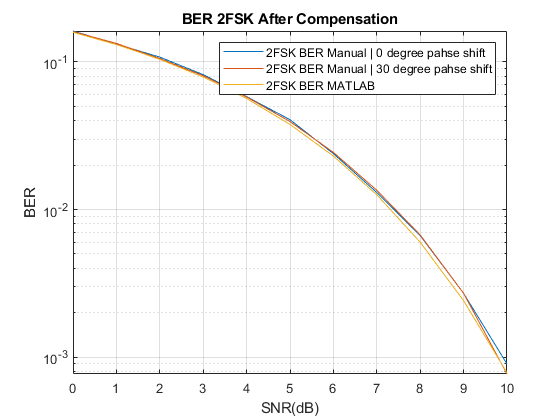

figure
[berFSK_matlab, serFSK_matlab] = berawgn(snr_db,modulation,M,'coherence');
semilogy(snr_db,berFSK(1,:))
hold on
semilogy(snr_db,berFSK(2,:))
hold on
semilogy(snr_db,berFSK_matlab)
hold on
legend('2FSK BER Manual | 0 degree pahse shift', '2FSK BER Manual | 30 degree pahse shift','2FSK BER MATLAB')
grid on
title('BER 2FSK After Compensation')
xlabel('SNR(dB)')
ylabel('BER')

In this section we have  phase offset. which have been compensated by using cross correlation of header which is known by reciever and transmitter.

 Phase offset is estimated by angle of maximum of correlation and its not accurate but it's value is close to real one.